dir1 = './GOOG.txt';
googlestock = readtable(dir1);

X = 1:253

X =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Mdl = fitlm(X,googlestock.Open)

Mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    _________    ______    ___________

    (Intercept)      118.8       0.98164    121.02    1.3775e-224
    x1             0.21078     0.0067005    31.457     4.5814e-89


Number of observations: 253, Error degrees of freedom: 251
Root Mean Squared Error: 7.78
R-squared: 0.798,  Adjusted R-Squared: 0.797
F-statistic vs. constant model: 990, p-value = 4.58e-89

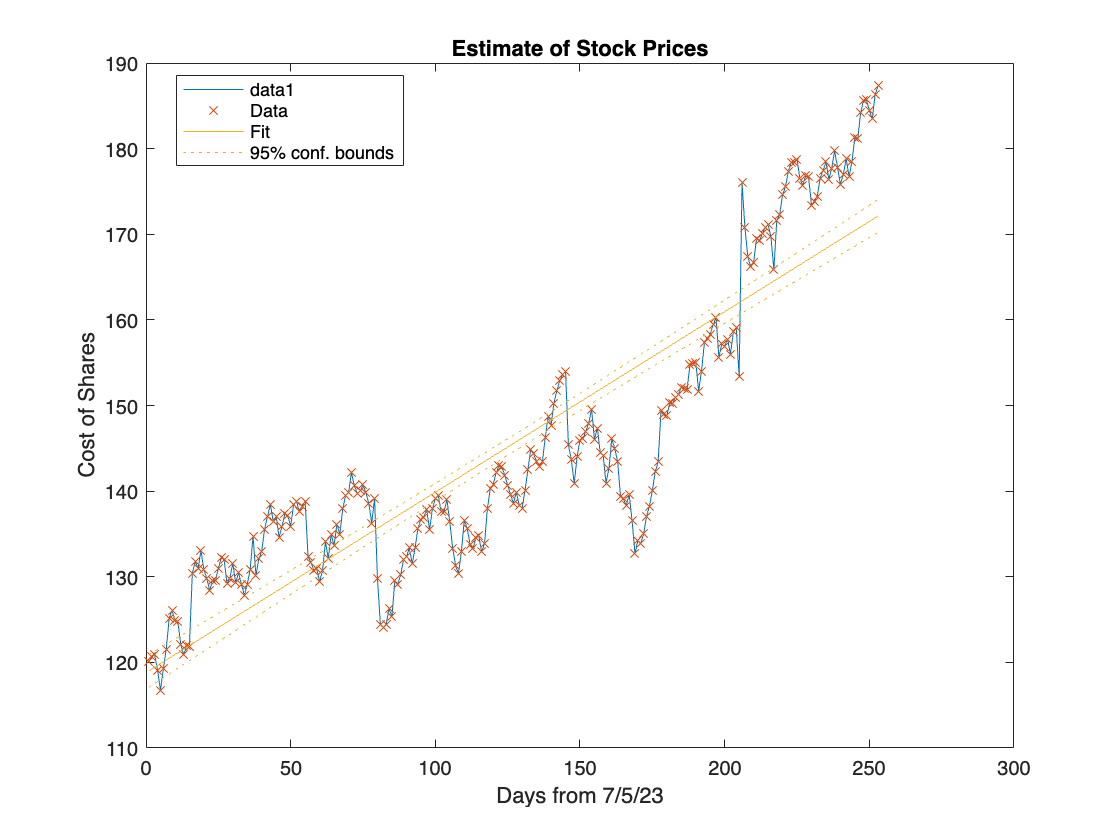


figure
plot(X, googlestock.Open)
hold on
plot(Mdl)
xlabel('Days from 7/5/23')
ylabel('Cost of Shares')
title('Estimate of Stock Prices')


coefs = polyfit(X, googlestock.Open, 1);
slope = coefs(1)

slope = 0.2108

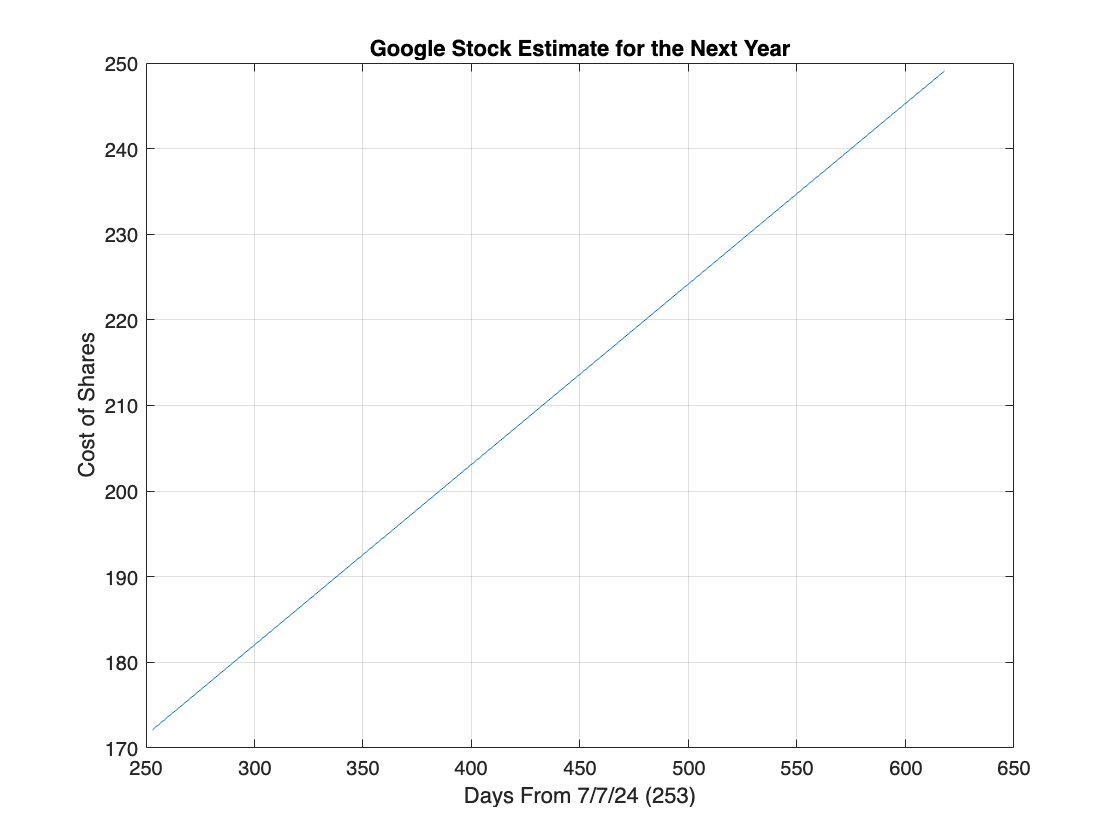

a = 0.2108;
b = 118.8006;
x = linspace(253, 618); 
y = a * x + b;

figure
plot(x, y)
grid on
xlabel('Days From 7/7/24 (253)')
ylabel('Cost of Shares')
title('Google Stock Estimate for the Next Year')